**Data**

x = [0    0.2    0.4    0.6    0.8    1.0    1.2    1.4    1.6    1.8    2.0]

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000



y = [0.5    0.7    0.7    0.6    0.9    0.8    1.3    1.6    1.9    2.3    2.4]

y =     0.5000    0.7000    0.7000    0.6000    0.9000    0.8000    1.3000    1.6000    1.9000    2.3000    2.4000


**Plot data**

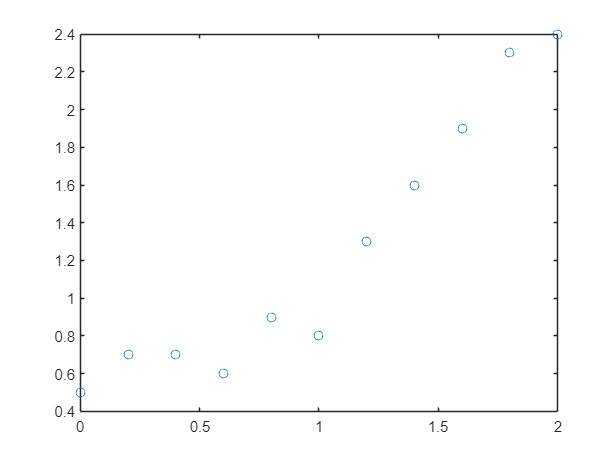

plot(x,y,"o")

**Transform data**

x

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


newy = log(y)

newy =    -0.6931   -0.3567   -0.3567   -0.5108   -0.1054   -0.2231    0.2624    0.4700    0.6419    0.8329    0.8755


**Perform linear regression & plot dataset + fitted line**

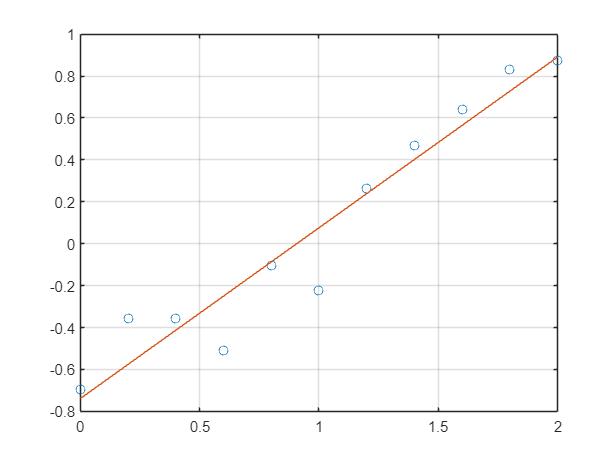

a =     0.8148   -0.7388


r2 = 0.9260

[a,r2] = linregr(x,newy)

**Computer parameters of nonlinear equation from the fitted line**

alpha = exp(a(2))

alpha = -0.7388

beta = a(1)

beta = 0.8148

**Plot the original data with the best fit nonlinear curve**

xx = 0 : 0.1 : 2

xx =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


yy = alpha * exp(beta * xx)

yy =    -0.7388   -0.8015   -0.8695   -0.9433   -1.0234   -1.1103   -1.2046   -1.3068   -1.4178   -1.5381   -1.6687   -1.8104   -1.9641   -2.1308   -2.3117   -2.5080   -2.7209   -2.9519   -3.2025   -3.4744   -3.7693


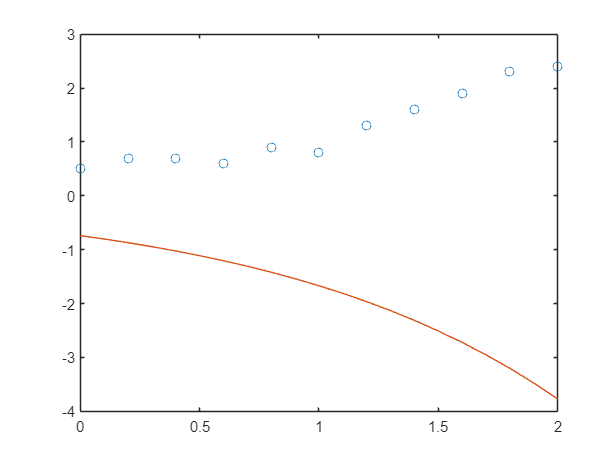


plot(x, y,'o',xx,yy,'-')

**Predict the value of y for the given x**

xtest = 1.1

xtest = 1.1000


predict_y = alpha * exp(beta * xtest)

predict_y = -1.8104